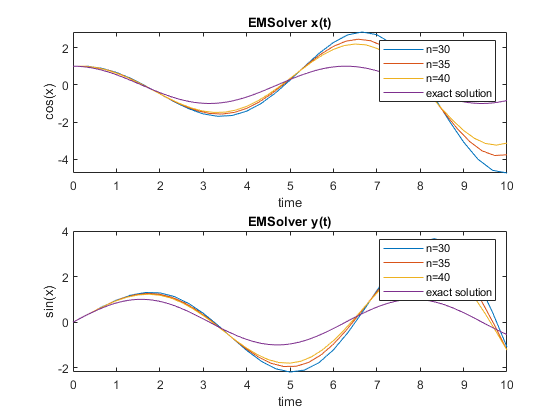

e = 0;
f = -1;
g = 1;
h = 0;
x_0 = 1;
y_0 = 0;
T=10;
N=[30,35,40];

figure
ax1 = subplot(2,1,1);
[x,y,t] = EMsolver(e,f,g,h,x_0,y_0,T,N(1));
plot(t,x)
hold on
[x,y,t] = EMsolver(e,f,g,h,x_0,y_0,T,N(2));
plot(t,x)
hold on
[x,y,t] = EMsolver(e,f,g,h,x_0,y_0,T,N(3));
plot(t,x)
hold on
t = 0:10/10^6:10;
x = cos(t);
plot(t,x)

title('EMSolver x(t)')
xlabel(ax1,'time')
ylabel(ax1,'cos(x)')
legend('n=30','n=35','n=40','exact solution')

ax2 = subplot(2,1,2);
[x,y,t] = EMsolver(e,f,g,h,x_0,y_0,T,N(1));
plot(t,y)
hold on
[x,y,t] = EMsolver(e,f,g,h,x_0,y_0,T,N(2));
plot(t,y)
hold on
[x,y,t] = EMsolver(e,f,g,h,x_0,y_0,T,N(3));
plot(t,y)
hold on
t = 0:10/10^6:10;
y = sin(t);
plot(t,y)

title('EMSolver y(t)')
xlabel(ax2,'time')
ylabel(ax2,'sin(x)')
legend('n=30','n=35','n=40','exact solution')

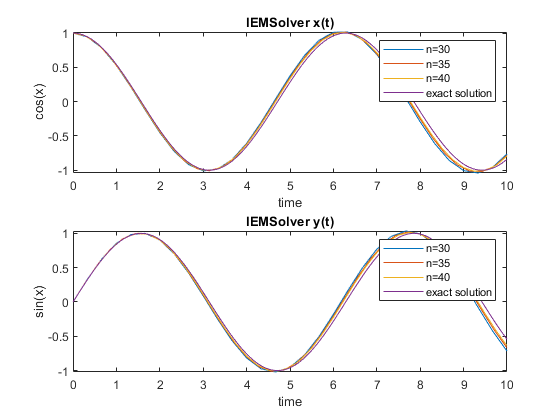


figure
ax1 = subplot(2,1,1);
[x,y,t] = IEMsolver(e,f,g,h,x_0,y_0,T,N(1));
plot(t,x)
hold on
[x,y,t] = IEMsolver(e,f,g,h,x_0,y_0,T,N(2));
plot(t,x)
hold on
[x,y,t] = IEMsolver(e,f,g,h,x_0,y_0,T,N(3));
plot(t,x)
hold on
t = 0:10/10^6:10;
x = cos(t);
plot(t,x)

title('IEMSolver x(t)')
xlabel(ax1,'time')
ylabel(ax1,'cos(x)')
legend('n=30','n=35','n=40','exact solution')

ax2 = subplot(2,1,2);
[x,y,t] = IEMsolver(e,f,g,h,x_0,y_0,T,N(1));
plot(t,y)
hold on
[x,y,t] = IEMsolver(e,f,g,h,x_0,y_0,T,N(2));
plot(t,y)
hold on
[x,y,t] = IEMsolver(e,f,g,h,x_0,y_0,T,N(3));
plot(t,y)
hold on
t = 0:10/10^6:10;
y = sin(t);
plot(t,y)

title('IEMSolver y(t)')
xlabel(ax2,'time')
ylabel(ax2,'sin(x)')
legend('n=30','n=35','n=40','exact solution')

function [x,y,t] = EMsolver(e,f,g,h,x_0,y_0,T,N)
    A = [e f; g h];
    dt = T/N;
    t = 0:dt:T;
    
    SOL = NaN(2,length(t));
    SOL(1,1) = x_0;
    SOL(2,1) = y_0;

    for(k = 2:length(t))
        % x_n = x_{n-1} + dt * dx_{n-1}/dt
        SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
    end

    x = SOL(1,:);
    y = SOL(2,:);
end

function [x,y,t] = IEMsolver(e,f,g,h,x_0,y_0,T,N)
 A = [e f; g h];
    dt = T/N;
    t = 0:dt:T;
    
    SOL = NaN(2,length(t));
    SOL(1,1) = x_0;
    SOL(2,1) = y_0;

    for(k = 2:length(t))
        % x_n = x_{n-1} + dt * dx_{n-1}/dt
        SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
        SOL(:,k) = SOL(:,k-1) + dt*1/2*(A*SOL(:,k-1) + A*SOL(:,k));
    end

    x = SOL(1,:);
    y = SOL(2,:);
end